# Step 1: Waypoints

The `waypoints` matrix stores the desired spatial locations of the drone. Each row corresponds to one waypoint, while the three columns represent the x, y, and z coordinates in metres. The points are arranged in the order in which the drone is expected to visit them.


$$\mathbf{p}_i =
\left[
\begin{array}{c}
x_i\\
y_i\\
z_i
\end{array}
\right]$$


The complete reference path can be represented as:


$$N = size(\mathbf{P},1)$$


The time between two consecutive waypoints is:


$$\Delta t_i = t_{i+1} - t_i$$


clc;
clear;
close all;
waypoints = [
    0   0   0;
    2   0   1;
    4   2   2;
    2   4   2;
    0   2   1;
    0   0   0];
N = size(waypoints, 1);

waypointTime = [0;2;4;6;8;10];

disp('Waypoint matrix:');

Waypoint matrix:


disp(waypoints);

     0     0     0
     2     0     1
     4     2     2
     2     4     2
     0     2     1
     0     0     0




disp('Waypoint times (s):');

Waypoint times (s):


disp(waypointTime);

     0
     2
     4
     6
     8
    10




fprintf('Number of waypoints = %d\n', N);

Number of waypoints = 6


The sequence of positions can be represented as:


$$\mathbf{p}_1 \rightarrow \mathbf{p}_2 \rightarrow \cdots \rightarrow \mathbf{p}_N$$


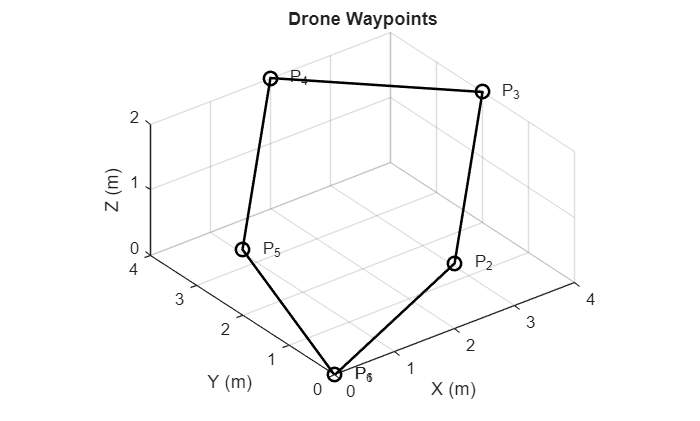

figure;

plot3(waypoints(:,1), ...
      waypoints(:,2), ...
      waypoints(:,3), ...
      'ko-', ...
      'LineWidth', 1.5, ...
      'MarkerSize', 8);

grid on;
axis equal;

xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');

title('Drone Waypoints');

% Label each waypoint
for i = 1:N

    text(waypoints(i,1), ...
         waypoints(i,2), ...
         waypoints(i,3), ...
         sprintf('  P_%d', i), ...
         'FontSize', 10);

end

The complete waypoint reference can therefore be viewed as:


$$\mathcal{T}_{ref} = \{(\mathbf{p}_i,t_i)\}_{i=1}^{N}
$$


This saved data becomes the **input to the next stage**, where the discrete waypoints and their timing can be converted into a continuous reference trajectory.

save('drone_toy_model.mat', ...
     'waypoints', ...
     'waypointTime');